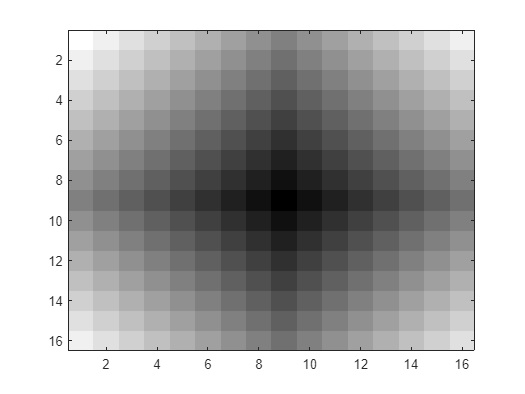

% 1.3 AVSTÅNDSFUNKTIONER
clf

distance_map = zeros(16,16);
for n = 1:16
    for m = 1:16
        distance_map(n,m) = manhat(n, m, 9, 9);
    end
end

figure; axis image; colormap gray;
imagesc(distance_map);

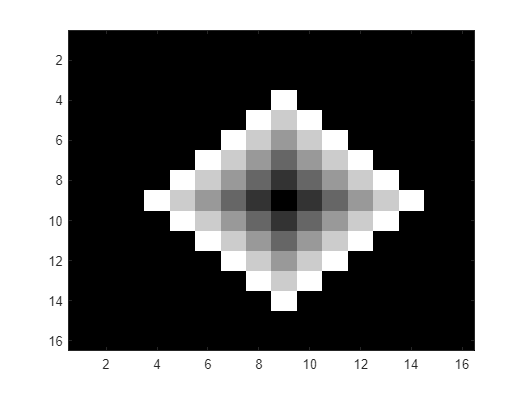


k = 5;
mask = (distance_map <= k);
distance_map = distance_map .* mask;

figure; axis image; colormap gray; 
imagesc(distance_map);

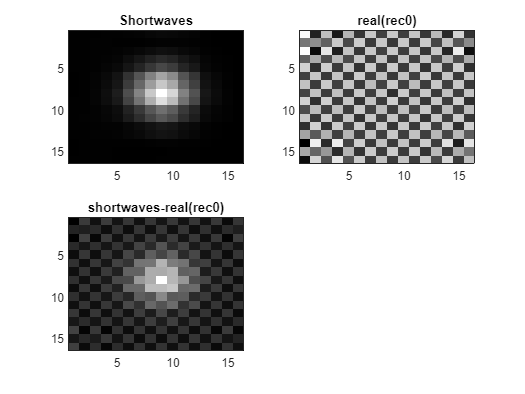

 pause Wait for user response.
    pause(n) pauses for n seconds before continuing, where n can also be a
    fraction. The resolution of the clock is platform specific. Fractional
    pauses of 0.01 seconds should be supported on most platforms.
 
    pause causes a procedure to stop and wait for the user to strike any
    key before continuing.
 
    pause OFF indicates that any subsequent pause or pause(n) commands
    should not actually pause. This allows normally interactive scripts to
    run unattended.
 
    pause ON indicates that subsequent pause commands should pause.
 
    pause QUERY returns the current state of pause, either 'on' or 'off'.
 
    STATE = pause(...) returns the state of pause previous to processing
    the input arguments.
 
    The accuracy of pause is subject to the sche

% 1.4 TVÅDIMENSIONELL FOURIERTRANSFORM AVV BILDER
% 1.)
load ("waves.mat");
ftwaves = fft2(waves);
imagesc(waves);

imagesc(abs(ftwaves));
plot(abs(ftwaves));

shiftwaves = fftshift(ftwaves);                         % Shifts ftwaves
imagesc(abs(shiftwaves));
plot(abs(shiftwaves));

shortwaves = waves(1:16:256,1:16:256);                  % ??
imagesc(abs(shortwaves));
plot(abs(shortwaves(2,:)))

shit1 = ifft2(fftshift(fftshift(fft2(shortwaves))));    % resultatet blir som riginal bilden shortwaves
imagesc(shit1);                                         % shit1 = shortwaves

% 2. 
% a)
ftshortwaves0 = fftshift(fft2(shortwaves)) .* mask;     % ??
imagesc(abs(ftshortwaves0));                            % Shows the dot that the mask lets through
mask = (distance_map <= 0);                             % All values bigger than 0 sets to 0

% b)
rec0 = fftshift(ifft2(ftshortwaves0));                  % rec0 = "vanlig bild"

% c)
imagesc(rec0);                                           % "vanlig bild"
imagesc(abs(rec0));                                      % "absolute value"
imagesc(abs(real(rec0)));                                % "real values"

% d)
subplot(2,2,1)
imagesc(shortwaves);
title("Shortwaves")
subplot(2,2,2)
imagesc(real(rec0));
title("real(rec0)")
subplot(2,2,3)
imagesc(shortwaves-real(rec0));
title("shortwaves-real(rec0)")